## MATLAB Code to Sketch the Expected Variation of pn(x,t)

### Define the x range, which is the distance from the pn junction

x = linspace(0, 10, 1000); % Arbitrary units


### Time instances after t = 0

t = [0, 1, 2, 3, 4, 5]; % Arbitrary units of time


### Define arbitrary values for initial hole concentration

#### Assume it decays exponentially over distance and time

p_n0 = 1e16; % Initial concentration at t=0 at the junction
D_p = 10; % Diffusion coefficient, arbitrary units
tau_p = 1; % Minority carrier lifetime, arbitrary units


### Initialize matrix to hold the pn(x,t) values

pn_xt = zeros(length(x), length(t));


#### Calculate the pn(x,t) values for each time instance

for i = 1:length(t)
    pn_xt(:,i) = p_n0 * exp(-x / sqrt(D_p * t(i))) * exp(-t(i) / tau_p);
end


### Plot the results

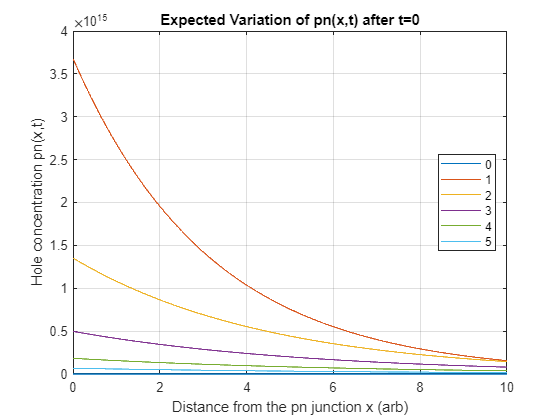

figure;
plot(x, pn_xt);
xlabel('Distance from the pn junction x (arb)');
ylabel('Hole concentration pn(x,t)');
title('Expected Variation of pn(x,t) after t=0');
legend(string(t), 'Location', 'east');
grid on;